# Hurricane Harvey

## Background and Scope

### Import the Data

The code below just imports the datafile

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 24);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["EpisodeID", "Event_ID", "State", "Year", "Month", "Event_Type", "CZ_Name", "Begin_Date_Time", "Timezone", "End_Date_Time", "Injuries_Direct", "Injuries_Indirect", "Deaths_Direct", "Deaths_Indirect", "Damage_Property", "Property_Cost", "Damage_Crops", "Crop_Cost", "Begin_Lat", "Begin_Lon", "End_Lat", "End_Lon", "Episode_Narrative", "Event_Narrative"];
opts.VariableTypes = ["double", "double", "categorical", "double", "categorical", "categorical", "categorical", "datetime", "double", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Event_Narrative", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["State", "Month", "Event_Type", "CZ_Name", "Episode_Narrative", "Event_Narrative"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Begin_Date_Time", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, "End_Date_Time", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, ["Timezone", "Damage_Property", "Damage_Crops"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["Timezone", "Damage_Property", "Damage_Crops"], "ThousandsSeparator", ",");

% Import the data
StormEvents2017finalProject = readtable("D:\coursera\matlab\Exploratory Data Analysis\Module 5\StormEvents_2017_finalProject.csv", opts);


%% Clear temporary variables
clear opts

data = StormEvents2017finalProject;
data = data(ismember(data.State,{'ARKANSAS','KENTUCKY','LOUISIANA','MISSISSIPPI','NORTH CAROLINA','TENNESSEE','TEXAS'}),:);
head(data)

ans = 8×24 table
    EpisodeID      Event_ID         State         Year     Month      Event_Type      CZ_Name        Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                    

### Two States Most Impacted by Harvey

So, we can group states' sum of property cost and sort it to find the most affected states.

% Remove NaN with 0
data.Property_Cost(ismissing(data.Property_Cost)) = 0;

% Group property cost in states
states = groupsummary(data, "State", "sum", "Property_Cost");

% sort the data
states = sortrows(states,'sum_Property_Cost','descend');
head(states)

ans = 7×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    TEXAS                3628          7.7777e+10    
    LOUISIANA             821          1.0761e+08    
    NORTH CAROLINA       1224          6.0612e+07    
    MISSISSIPPI          1033           5.707e+07    
    ARKANSAS             1212          3.7586e+07    
    KENTUCKY             1345          2.8104e+07    
    TENNESSEE            1404          2.7161e+07    


**Texas and Louisiana** are the most affected states

### Table of Events for Two Most Impacted States

Two_Most_Impactes_States = data(data.State == "TEXAS" | data.State == "LOUISIANA", :);
head(Two_Most_Impactes_States)

ans = 8×24 table
    EpisodeID      Event_ID     State    Year     Month        Event_Type         CZ_Name       Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                 Episode_Narrative                                                                             

## Visualizations

### Figure of Event Types

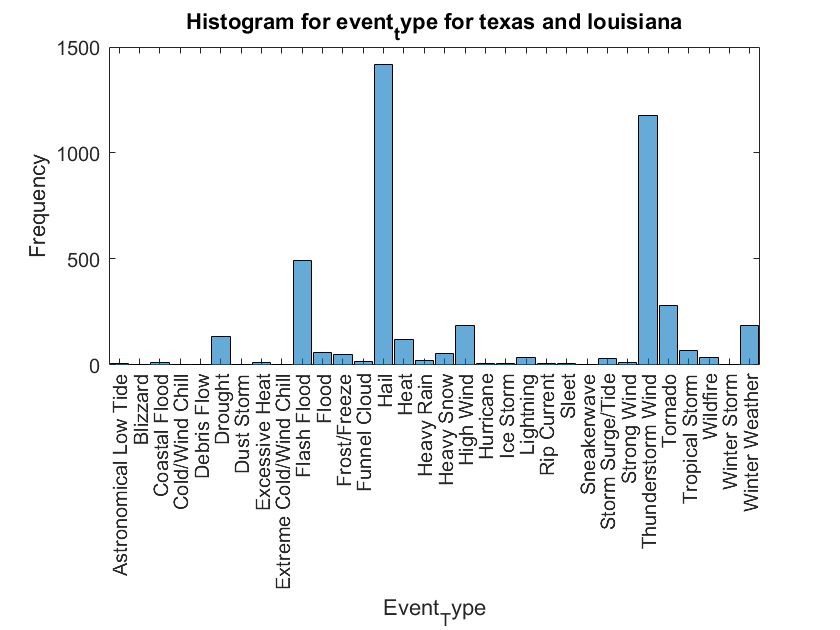

% Remove entries in Event_Type with zero frequency as this would make it easy to read histogram
Two_Most_Impactes_States_Compact = removecats(Two_Most_Impactes_States.Event_Type,{'Avalanche','Dense Fog','Dense Smoke','Dust Devil','Freezing Fog','High Surf','Lake-Effect Snow','Lakeshore Flood','Marine Hail','Marine High Wind','Marine Hurricane/Typhoon','Marine Strong Wind','Marine Thunderstorm Wind','Marine Tropical Depression','Marine Tropical Storm','Tropical Depression','Waterspout'});

histogram(Two_Most_Impactes_States_Compact)

% Some additions
xlim({'Astronomical Low Tide','Winter Weather'})
ylim([0 1500])
title('Histogram for event_type for texas and louisiana')
xlabel('Event_Type')
ylabel('Frequency')

### Figure of Event Locations

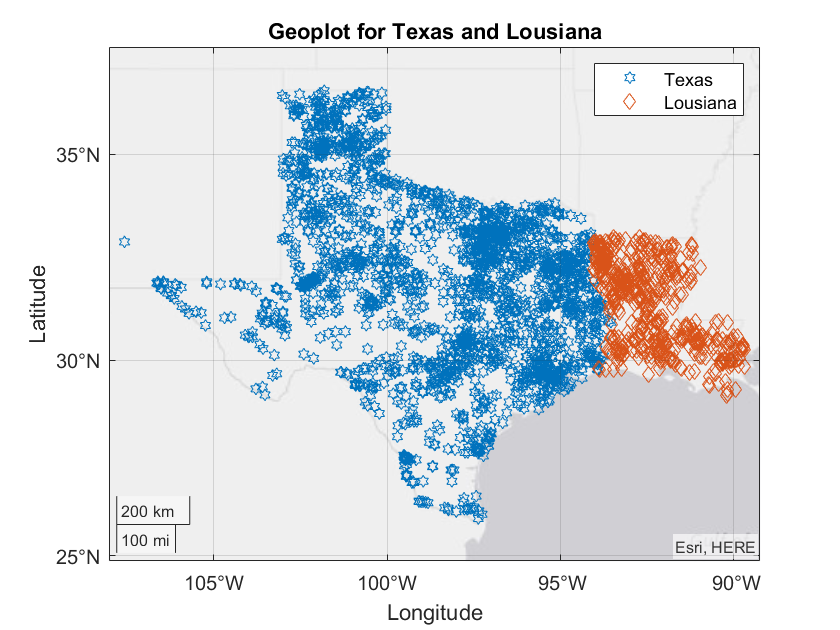

Texas_Events = data(data.State == "TEXAS", :);
Lousiana_Events = data(data.State == "LOUISIANA", :);

geoscatter(Texas_Events.Begin_Lat, Texas_Events.Begin_Lon, "Marker","hexagram")
hold on
geoscatter(Lousiana_Events.Begin_Lat, Lousiana_Events.Begin_Lon, "Marker","diamond")
hold off

legend({'Texas','Lousiana'})
title('Geoplot for Texas and Lousiana')

## Analysis

### Three Counties with Most Events in State 1

We can get group counts from the groupcounts function for the counties and then sort it to get the top three resutls

Counties_in_Texas = groupcounts(Texas_Events, "CZ_Name");

% Sort
Couties_in_Texas = sortrows(Counties_in_Texas,'GroupCount','descend');
head(Couties_in_Texas)

ans = 8×2 table
                    CZ_Name                    GroupCount
    _______________________________________    __________

    COLLIN                                         64    
    HARRIS                                         64    
    TARRANT                                        63    
    MIDLAND                                        61    
    DENTON                                         59    
    GUADALUPE MOUNTAINS OF CULBERSON COUNTY        59    
    POTTER                                         49    
    ECTOR                                          46    


So the three most affected counties in Texas are:

- **Collin**

- **Harris**

- **Tarrant**

### Three Counties with Most Events in State 2

Similarly, we can find the three most affected counties for Louisiana

Counties_in_Lousiana = groupcounts(Lousiana_Events, "CZ_Name");

% Sort
Couties_in_Lousiana = sortrows(Counties_in_Lousiana,'GroupCount','descend');
head(Couties_in_Lousiana)

ans = 8×2 table
      CZ_Name       GroupCount
    ____________    __________

    CADDO               65    
    NATCHITOCHES        52    
    SABINE              26    
    WINN                26    
    CALCASIEU           25    
    ST. TAMMANY         24    
    GRANT               23    
    BOSSIER             22    


So the three most affected counties in Texas are:

- **Caddo**

- **Natchitoches**

- **Sabine**

### Three Counties with Highest Property Cost in State 1

Counties_in_Texas = groupsummary(Texas_Events, "CZ_Name", "sum", "Property_Cost");

% Sorting
Counties_in_Texas = sortrows(Counties_in_Texas,'sum_Property_Cost','descend');

Counties_in_Texas = 268×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    GALVESTON           34                2e+10    
    FORT BEND           31           1.6006e+10    
    MONTGOMERY          12              1.4e+10    
    HARRIS              64           1.0002e+10    
    JEFFERSON           29                3e+09    
    BRAZORIA            25           2.0015e+09    
    ARANSAS             13           1.9504e+09    
    ORANGE               9              1.5e+09    
    NUECES              32           1.3016e+09    
    WALKER              12              1.2e+09    
    LIBERTY             10                1e+09    
    SAN JACINTO          6                7e+08    
    POLK                 7           6.0005e+08    
    HARDIN               8                6e+08    
    SAN PATRICIO        11       

head(Counties_in_Texas)

ans = 8×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    GALVESTON         34                2e+10    
    FORT BEND         31           1.6006e+10    
    MONTGOMERY        12              1.4e+10    
    HARRIS            64           1.0002e+10    
    JEFFERSON         29                3e+09    
    BRAZORIA          25           2.0015e+09    
    ARANSAS           13           1.9504e+09    
    ORANGE             9              1.5e+09    


This tells us that for Texas, the following were the counties worst affected in terms of property cost:

- **Galveston      $ 2 x **${10}^{10}$

- **Fort Bend      $ 1.6 x **${10}^{10}$

- **Montgomery  $ 1.4 x **${10}^{10}$

### Three Counties with Highest Property Cost in State 2

Counties_in_Lousiana = groupsummary(Lousiana_Events, "CZ_Name", "sum", "Property_Cost");

% Sorting
Counties_in_Lousiana = sortrows(Counties_in_Lousiana,'sum_Property_Cost','descend');

Counties_in_Lousiana = 77×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    CALCASIEU           25           6.1268e+07    
    BEAUREGARD          10           1.5261e+07    
    AVOYELLES           10             7.15e+06    
    RAPIDES             20            6.321e+06    
    ORLEANS             11                5e+06    
    EVANGELINE           6             3.66e+06    
    LA SALLE            12            2.015e+06    
    BOSSIER             22                8e+05    
    NATCHITOCHES        52              7.7e+05    
    FRANKLIN            12             6.75e+05    
    CATAHOULA            6              5.5e+05    
    ACADIA              18              4.8e+05    
    ALLEN               18             4.39e+05    
    RICHLAND             8             3.47e+05    
    MOREHOUSE            9     

head(Counties_in_Lousiana)

ans = 8×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    CALCASIEU         25           6.1268e+07    
    BEAUREGARD        10           1.5261e+07    
    AVOYELLES         10             7.15e+06    
    RAPIDES           20            6.321e+06    
    ORLEANS           11                5e+06    
    EVANGELINE         6             3.66e+06    
    LA SALLE          12            2.015e+06    
    BOSSIER           22                8e+05    


This tells us that for Texas, the following were the counties worst affected in terms of property cost:

- **Calcasieu     $ 61268000**

- **Beauregard  $ 15261000**

- **Avoyelles     $ 7150000**

## Conclusions and Recommendations

The above analysis and visualization conclude that the following places were most affected by Harvey:

- **Collin**

- **Harris**

- **Tarrant**

- **Caddo**

- **Natchitoches**

- **Sabine**

- **Galveston**

- **Fort Bend **

- **Montgomery**

- **Calcasieu**

- **Beauregard**

- **Avoyelles**

Also as seen in the values, Counties in Texas are more affected than counties in Louisiana